Process Sensor Streams 

% Load rosbag data 
bagSelect = rosbag('2022-08-01-00-10-02.bag')

bagSelect =   BagSelection with properties:

           FilePath: 'C:\Users\johni\github\Thesis-\Control Algorithms\Navigation_Stack\Experiment_1_Plots\2022-08-01-00-10-02.bag'
          StartTime: 1.6593e+09
            EndTime: 1.6593e+09
        NumMessages: 4181
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [4181×4 table]



% Capture data on /zlac8015d/encoder topic 
encoderLog = select(bagSelect, 'Topic','/zlac8015d/encoder');
encoderPlot = readMessages(encoderLog);

% Determine vector length
[encoderLength,~] = size(encoderPlot);

% Preallocate array sizes
leftEncoder = zeros(encoderLength,1);
rightEncoder = zeros(encoderLength,1);
leftRPM = zeros(encoderLength,1);
rightRPM = zeros(encoderLength,1); 

% Parse data 
for i = 1:encoderLength
    leftEncoder(i,1) = encoderPlot{i}.Data(1,:);
    rightEncoder(i,1) = -encoderPlot{i}.Data(2,:);
    leftRPM(i,1) = encoderPlot{i}.Data(3,1); 
    rightRPM(i,1) = encoderPlot{i}.Data(4,1); 
end 

% Time parsing
timeLog = encoderLog.MessageList.Time; 
encoderTime = zeros(length(timeLog), 1); 
encoderTimeStep = zeros(length(timeLog), 1);

% Calculate time 
for i = 1:(length(timeLog))
    encoderTime(i,1) = (timeLog(i) -  timeLog(1));
end

% Calculate time step 
for i = 1:(length(encoderTime) - 1)
    encoderTimeStep(i,1) = encoderTime(i+1,1) - encoderTime(i,1);  
end

Process Pose Calculations

load('experiment_1_encoder_pose.mat'); 
truth = readmatrix('truth.txt'); 

Plot Estimated Encoder Poses

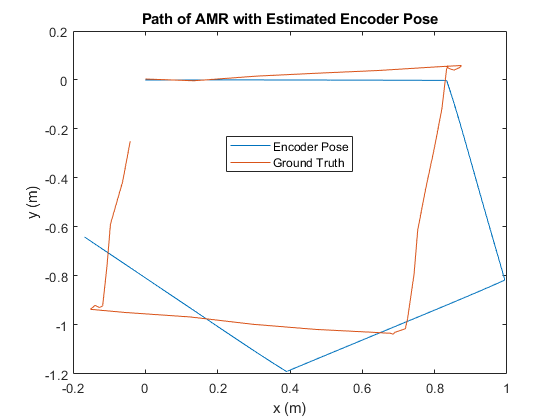

plot(out.encoderPose.Data(:,1), out.encoderPose.Data(:,2));
hold on
title('Path of AMR with Estimated Encoder Pose');
xlabel('x (m)');
ylabel('y (m)');
plot(-truth(:,2), -truth(:,3)); 
legend('Encoder Pose', 'Ground Truth', 'Location','best')
hold off 

Plot Wheel Encoder Data

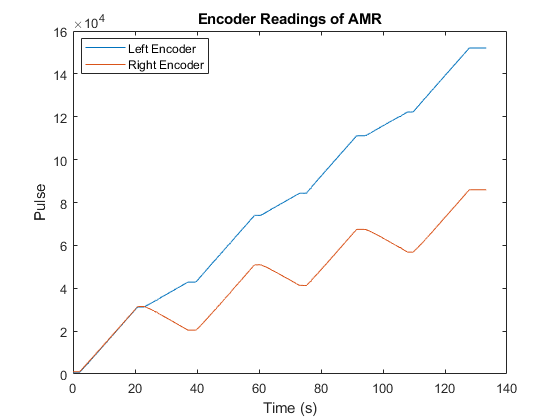

plot(encoderTime, leftEncoder);
hold on
title('Encoder Readings of AMR');
xlabel('Time (s)');
ylabel('Pulse');    
plot(encoderTime, rightEncoder);
legend('Left Encoder', 'Right Encoder', 'Location', 'best')
hold off 

Plot Calculated RPM Data 

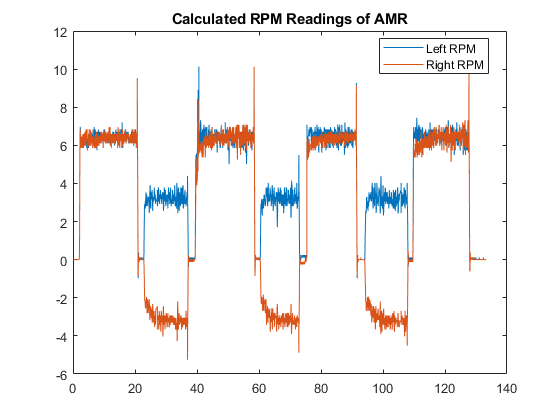

calcLeftRPM = zeros(encoderLength - 1, 1); 
calcRightRPM = zeros(encoderLength - 1, 1); 
leftFreq = zeros(encoderLength - 1, 1); 
rightFreq = zeros(encoderLength - 1, 1); 
leftEncoderChange = zeros(encoderLength - 1, 1);
rightEncoderChange = zeros(encoderLength - 1, 1);

% Calculate Frequency 
for i = 1:(encoderLength - 1)
    leftFreq(i,1) = (leftEncoder(i+1) - leftEncoder(i))/0.03;
    rightFreq(i,1) = (rightEncoder(i+1) - rightEncoder(i))/0.03;
end

% Calcualte RPM 
for i = 1:length(leftFreq)
    calcLeftRPM(i,1) = (leftFreq(i,1)*15.0)/4096.0; 
    calcRightRPM(i,1) = (rightFreq(i,1)*15.0)/4096.0; 
end

%Calcualte Encoder Change 
for i = 1:(encoderLength - 1)
    leftEncoderChange(i,1) = leftEncoder(i+1) - leftEncoder(i); 
    rightEncoderChange(i,1) = rightEncoder(i+1) - rightEncoder(i); 
end

plot(encoderTime(2:end), calcLeftRPM);
hold on 
title('Calculated RPM Readings of AMR');
plot(encoderTime(2:end), calcRightRPM); 
legend('Left RPM', 'Right RPM', 'Location', 'best')
hold off 

Plot Measured RPM Data 

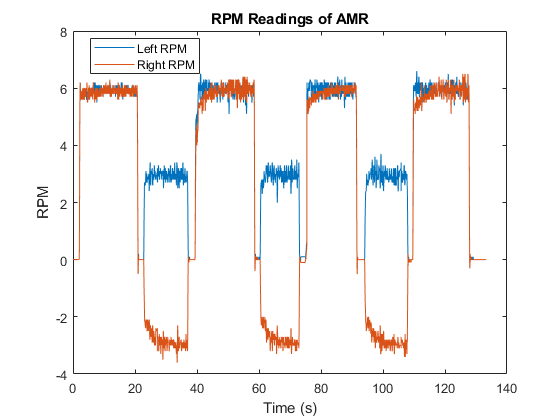

plot(encoderTime, leftRPM);
hold on
title('RPM Readings of AMR');
xlabel('Time (s)');
ylabel('RPM');
plot(encoderTime, rightRPM);
legend('Left RPM', 'Right RPM', 'Location', 'best')
hold off